clear;
load processed_thruster_data.mat;
dataVal = data_square;
dataEst = data_sine;

% prepare tfsrivcstruc
% parameter numbers numerator
nz_min = 0; nz_max = 3;
% parameter numbers denominator
np_min = 1; np_max = 3;

nn = [nz_min np_min; nz_max np_max]

nn =      0     1
     3     3


% we supply dataValid, cross validation is integrated
V = tfsrivcstruc(dataEst, dataVal, nn);


Elapsed time :  0 h  0 min  7 s 



determine model with simple structer and good fit, validate it on filtered data

selcstruc(V,'tfsrivc','Nmodels',10);


    Note: The value for 'Nmodels' is greater than the number of available models.



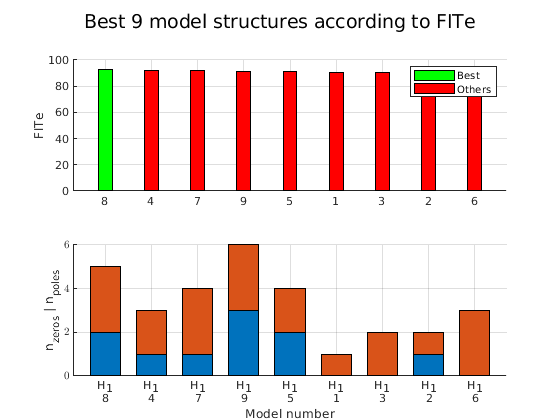

saveFigure(gcf, 'figuresSoftlink/tfsrivcstruc')

bestModelNumber = 1;
% model four also seems good!
nz_best = V(bestModelNumber, 1);
np_best = V(bestModelNumber, 2);

% estimate delay by setting it to NaN
% M = tfest(dataEst, np_best, nz_best, NaN);
M = tfsrivc(dataEst, np_best, nz_best);
present(M);

                                                                                                                       
M =                                                                                                                    
                                                                                                                       
  From input "u1" to output "Force":                                                                                   
                                    3.781 (+/- 0.009472)                                                               
  exp(-(0.00323 +/- 7.35e-05)*s) * ----------------------                                                              
                                   s + 126.6 (+/- 0.3287)                                                              
                                                                                                                       
Continuous-time identified transfer func

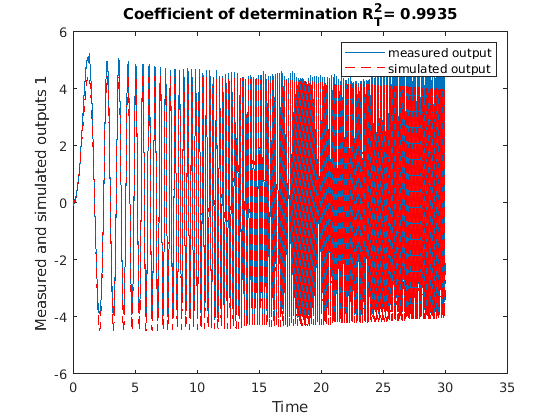

% second order one zero model (plus small delay)
figure;
comparec(dataEst, M);

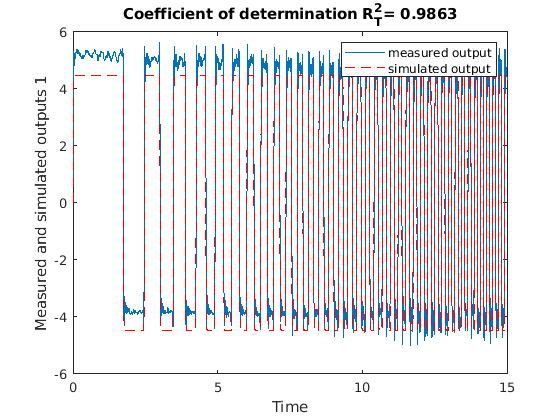

comparec(dataVal, M);

compare model to noisy (but shifted) data

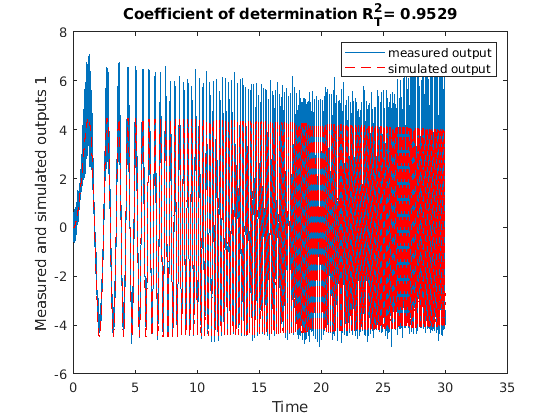

figure;
comparec(data_sine_unfiltered, M);
saveas(gcf, 'figuresSoftlink/tfsrivc-fit-sine-unfiltered-png.png')

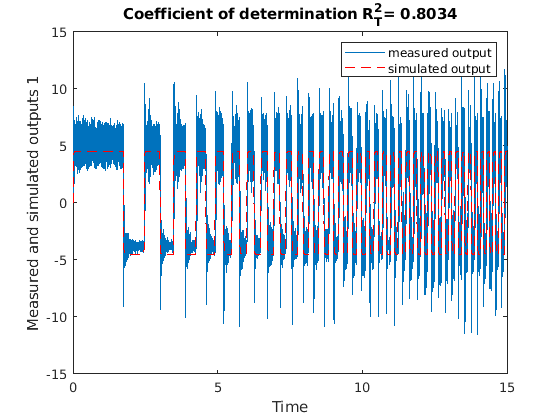

figure;
comparec(data_square_unfiltered, M);
saveas(gcf, 'figuresSoftlink/tfsrivc-fit-square-unfiltered-png.png')

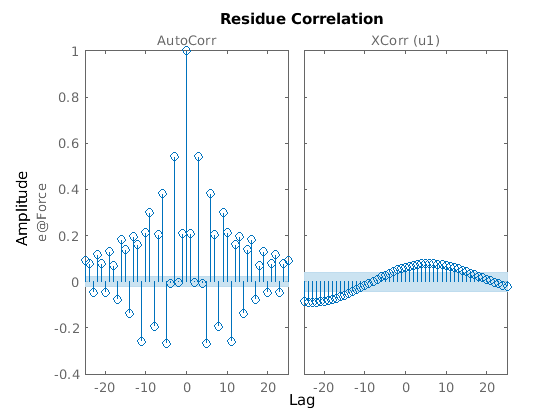

resid(data_sine_unfiltered, M);

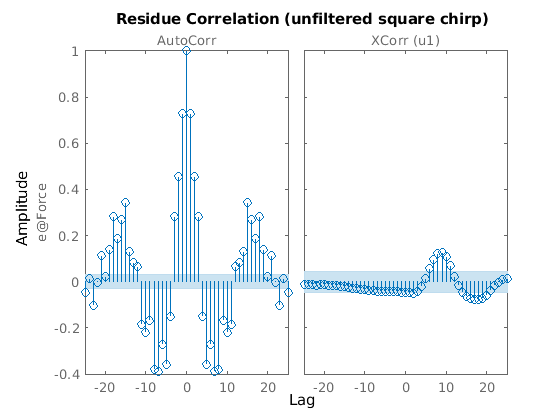

resid(data_square_unfiltered, M);
title('Residue Correlation (unfiltered square chirp)')
saveas(gcf, 'figuresSoftlink/tfsrivc-resid-square.png')

Try to find ARMA model to better understand noise

not really successful because pattern in residuals that corresponds to non-linear properties of the model

sysInit = idproc("P1D");
sysInit.Kp = dcgain(M);
sysInit.Tp1 = 1 / M.Denominator(2);
sysInit.Td = M.IODelay;
opt = procestOptions('DisturbanceModel','ARMA1');
% important : procest on unfiltered data to get a good noise model
sysP1D = procest(data_sine_unfiltered, sysInit, opt);
present(sysP1D)

                                                                   
sysP1D =                                                           
Process model with transfer function:                              
             Kp                                                    
  G(s) = ---------- * exp(-Td*s)                                   
          1+Tp1*s                                                  
                                                                   
        Kp = 0.028994 +/- 7.2565e-05                               
       Tp1 = 0.00036852 +/- 0.0037966                              
        Td = 0.009972 +/- 0.00038793                               
                                                                   
An additive ARMA disturbance model has been estimated              
      y = G u + (C/D)e                                             
                                                                   
      C(s) = s + 10.58 (+/- 0.3345)             

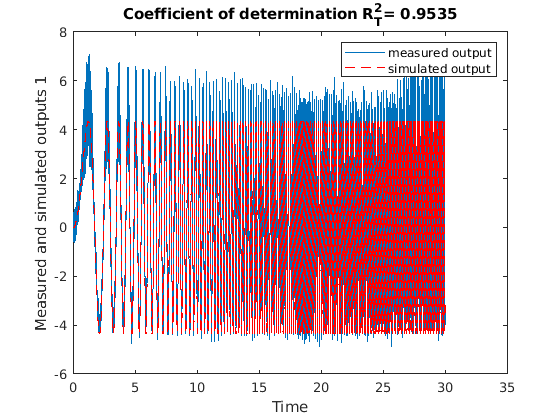

% evaluate
figure;
comparec(data_sine_unfiltered, sysP1D);
% saveFigure(gcf, 'figuresSoftlink/sysP1D-fit-sine-unfiltered')
saveas(gcf, 'figuresSoftlink/sysP1D-fit-sine-unfiltered-png.png')

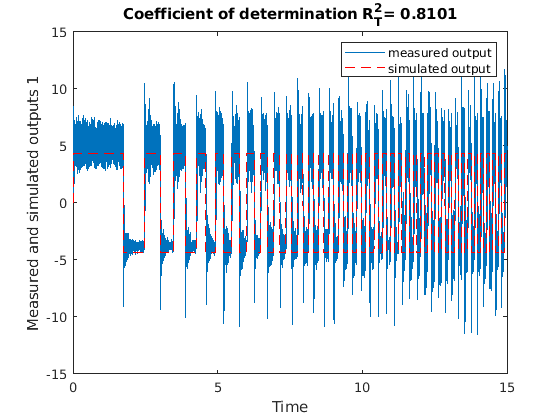


figure;
comparec(data_square_unfiltered, sysP1D);
% saveFigure(gcf, 'figuresSoftlink/sysP1D-fit-square-unfiltered')
saveas(gcf, 'figuresSoftlink/sysP1D-fit-square-unfiltered-png.png')

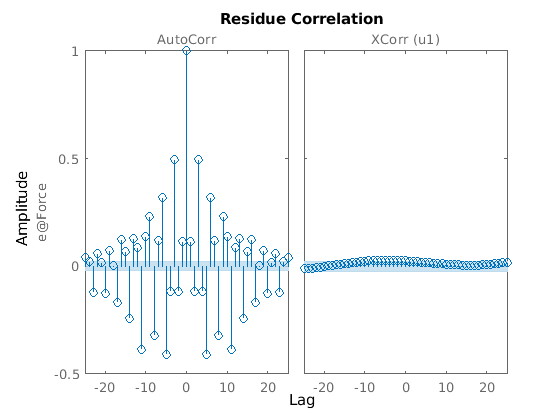

resid(data_sine_unfiltered, sysP1D);

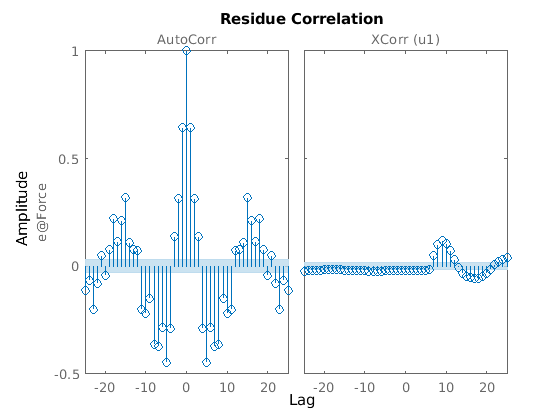

resid(data_square_unfiltered, sysP1D);


% store models
storeNewModel(M, 'M_tfsrivc')
storeNewModel(sysP1D, 'M_procest')